# PCA Example for DSFEII

Author: Dimitar Ninevski

Date: 15.10.2024

## Prepare workspace

close all;
clear;

## Load dataset

load PointCloud.mat;

## Visualize data

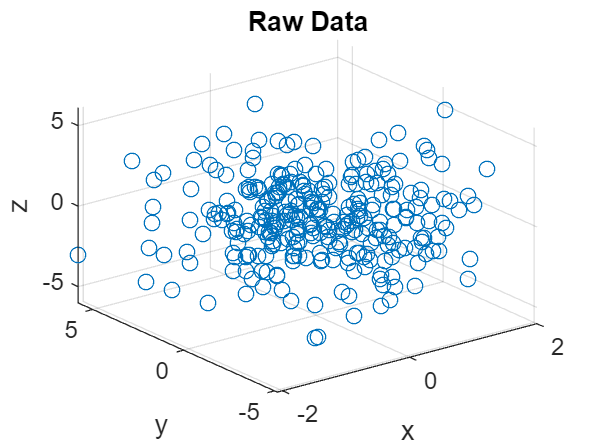

x = X(:,1);
y = X(:,2);
z = X(:,3);
fig1 = figure;
scatter3(x,y,z);
xlabel('x');
ylabel('y');
zlabel('z');
title('Raw Data')

## Perform PCA using SVD

We are going to use Singular Value Decomposition (SVD) to perform Principal Component Analysis (PCA)

First we do the SVD

[U,S,V] = svd(X, 0);

Choose how many dimensions to "keep"

k = 2;
V2 = V(:,1:k);

Perform PCA

P = X*V2;

## Visualize PCA results

p1 and p2 are the first two principal components.

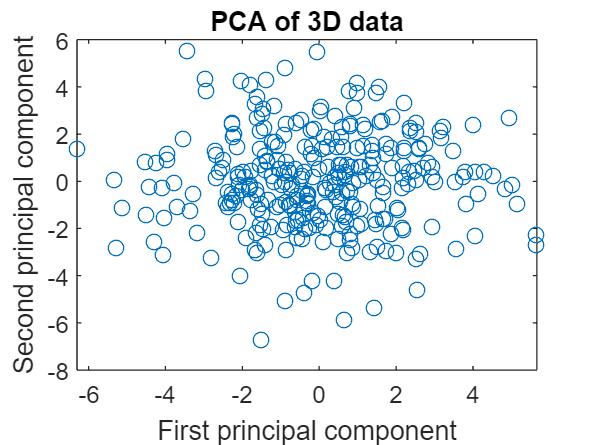

p1 = P(:,1);
p2 = P(:,2);
fig2 = figure;
plot(p1, p2, 'o');
xlabel('First principal component')
ylabel('Second principal component')
title('PCA of 3D data');

## Compute the percentage of the variance kept

varMat = S.^2;
variances = diag(varMat);
sumVariances = sum(variances);
percentages = 100*variances/sumVariances

percentages =    52.8278
   46.9313
    0.2409


# CCA Example for DSFEII

Perform CCA on the carbig dataset

load carbig;

Define the datasets

A = [Displacement, Horsepower, Weight];
B = [Acceleration, MPG];
dataCar = [A, B];
indicesOfNans = sum(isnan(dataCar),2);
dataWithoutNans = dataCar(~indicesOfNans,:);
meanFreeData = dataWithoutNans - mean(dataWithoutNans);
AWithoutNans = meanFreeData(:,1:3);
BWithoutNans = meanFreeData(:,4:5);

Perform CCA

[Ac,Bc,rc,Uc,Vc] = canoncorr(AWithoutNans,BWithoutNans)

Ac =     0.0025    0.0048
    0.0202    0.0409
   -0.0000   -0.0027


Bc =    -0.1666   -0.3637
   -0.0916    0.1078


rc =     0.8782    0.6328


Uc =     0.7843    0.1737
    1.5940    1.3053
    1.2174    1.2266
    1.1824    1.1677
    0.9751    0.7061
    2.4421    1.2987
    2.9486    2.2835
    2.8136    2.1244
    3.0503    2.3028
    2.1951    2.0992


Vc =     1.0886    0.7011
    1.4466    0.5596
    1.2553    1.0649
    1.2717    0.4856
    1.4301    1.1389
    1.6965    1.1052
    1.9547    1.3612
    2.0380    1.5431
    1.7881    0.9975
    1.9465    1.6509


Visualize results

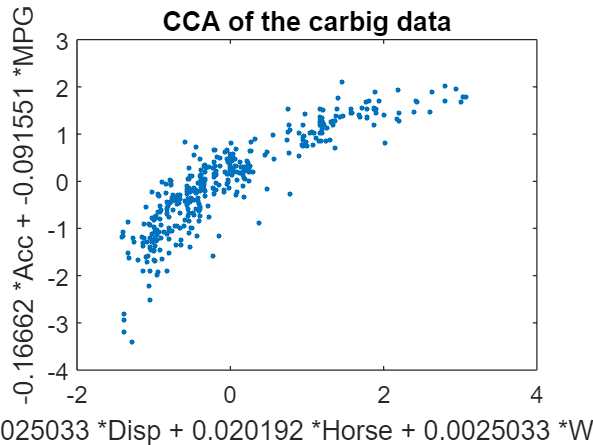

fig3 = figure;
plot(Uc(:,1), Vc(:,1), '.');
title('CCA of the carbig data');
xlabel([num2str(Ac(1,1)),' *Disp + '...
    ,num2str(Ac(2,1)),' *Horse + '...
    ,num2str(Ac(1,1)),' *Weight'])
ylabel([num2str(Bc(1,1)),' *Acc + '...
    ,num2str(Bc(2,1)),' *MPG'])